## 旋转-平移顺序

v0 = [1,1];
v0 = v0./norm(v0,2);

p0 = [1, -1; 3, 1; 1, 3; -1, 1; 1, -1];
p0 = p0';
c = [4;2];
p0 = p0 + ndgrid(c,1:5);

theta = pi/2 - atan2(v0(2),v0(1));
R = rotz(theta);
R = R(1:2,1:2);
p1 = R*p0 - R*ndgrid(c,1:5);
p2 = R*p0 - ndgrid(c,1:5);
p3 = R*p0;

figure;
% line([0,v0(1)],[0,v0(2)],'b'); hold on;
plot(p0(1,:),p0(2,:),'b'); hold on;
p0Cx = (p0(1,1)+p0(1,4))/2

p0Cx = 4

p0Cy = (p0(2,1)+p0(2,4))/2

p0Cy = 2

scatter(p0Cx,p0Cy,'b');
plot(p1(1,:),p1(2,:),'r');
scatter((p1(1,1)+p1(1,4))/2,(p1(2,1)+p1(2,4))/2,'r');
plot(p2(1,:),p2(2,:),'y');
scatter((p2(1,1)+p2(1,4))/2,(p2(2,1)+p2(2,4))/2,'y');
plot(p3(1,:),p3(2,:),'k');
p3Cx = (p3(1,1)+p3(1,4))/2

p3Cx = 1.4142

p3Cy = (p3(2,1)+p3(2,4))/2

p3Cy = 4.2426

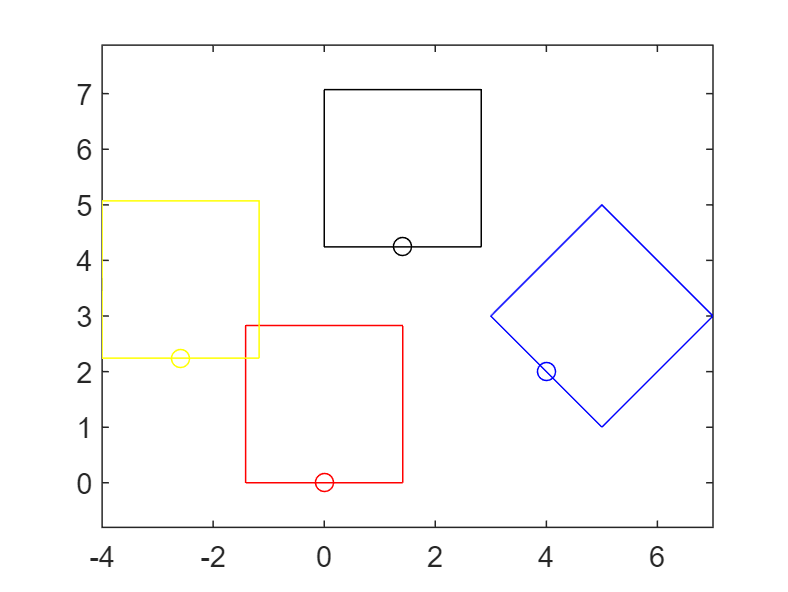

scatter(p3Cx,p3Cy,'k');
axis equal;


ang = acosd((p0Cx*p3Cx + p0Cy*p3Cy)/sqrt(p0Cx^2+p0Cy^2)/sqrt(p3Cx^2+p3Cy^2))

ang = 45

## 旋转顺序

addpath(genpath('../funcs'));
tic
for ii = 1:1000
    x = pi*rand;
    y = pi*rand;
    z = pi*rand;
    p0 = [0;0;1];
    q0 = [0;1;0];
    % p = [0.75;0.433;0.5];
    % q = [-0.5;0.866;0];
    p = rotz(z)*roty(y)*rotx(x)*p0;
    q = rotz(z)*roty(y)*rotx(x)*q0;
    
    R21 = vecRot(p0,p);
    p21 = R21*p0; % ~= p
    q21 = R21*q0;
    R22 = vecRot(q21,q);
    p22 = R22*p21; % ~= I*p1
    q22 = R22*q21;
    
    R11 = vecRot(q0,q);
    p11 = R11*p0; % ~= p
    q11 = R11*q0;
    R12 = vecRot(p11,p);
    p12 = R12*p11; % ~= I*p1
    q12 = R12*q11;
    
    if (norm(q12 - q22)>0.005 || norm(p12 - p22)>0.005)
        break;
    end
end
toc;

历时 14.872085 秒。


rmpath(genpath('../funcs'));

## 刀具找最近点

addpath(genpath('../funcs'));
n1 = [0;0;1];
a1 = [1;0;0];
R = vecRot(n1,a1);
x = pi*rand;
y = pi*rand;
z = pi*rand;
n2 = rotz(z)*roty(y)*rotx(x)*n1;
a2 = rotz(z)*roty(y)*rotx(x)*a1;
t = 0:0.1:1;
n = (1 - t).*n1 + t.*n2;
n = n./vecnorm(n,2,1);
a = (1 - t).*a1 + t.*a2;
a = a./vecnorm(a,2,1);

abs(R*n - a)

ans =          0    0.0002    0.0058    0.0329    0.1080    0.2469    0.4155    0.5522    0.6302    0.6596    0.6589
         0    0.0776    0.1603    0.2434    0.3231    0.4017    0.4846    0.5680    0.6412    0.6983    0.7392
    0.0000    0.1022    0.2383    0.4145    0.6207    0.8119    0.9310    0.9673    0.9532    0.9198    0.8830



rmpath(genpath('../funcs'));

说明：(1 - t) * n1 + t * n2的公式，如果将两个旋转前后的坐标系的x、y、z轴分别代入计算后，得到的新坐标系的三轴垂直关系无法保证。

## residual3D验证

toolName = '..\output_data\tool\toolTheo_3D.mat';
toolData = load(toolName);
uLim1 = [0,1];
uLim2 = [0,1];
[res,peakPt,uLim1,uLim2] = residual3D(toolPt,toolNorm,toolCutDirect, ...
  toolContactU,sp,toolRadius,uLim1,uLim2,ind1,ind2,ind3);